# Sleep Staging

## Path information

The first section is simply creating the paths to the EEG data and loading in the data. Please change the path, if necessary. Please enter the subject and run information in the format shown below.

Example: 

subjectID = osceeg17b;

run = run01;

subjectID = 'osceeg17b';


run = 'run01';


mainpath = ['/Volumes/Research/eng_research_lewislab/data/osceeg_frommgh/',subjectID];
channelpath = [mainpath,'/eeg/fs200_averef_regbcg/', run];
hdrpath = [mainpath,'/eeg/fs200_averef_regbcg/', run, '/hdr'];
ecgpath = [mainpath,'/eeg/fs200_averef_regbcg/', run, '/ecg'];
resppath = [mainpath,'/eeg/fs200_averef_regbcg/', run, '/resp'];

% Loop to check which channel to go to
occchan = occ_chan_per_subj(subjectID);
load([channelpath,'/c',num2str(occchan)]);
EEG = ch;
eegtitle = ['EEG Channel', num2str(occchan)];

% Load EEG/ECG data
load(ecgpath);
ECG = ch;

load(hdrpath);
timeEEG = hdr.ts;


 


## Specgram & Click Times Plotting

This section plots the click times and the spectrogram on the same figure to assist in sleep staging.

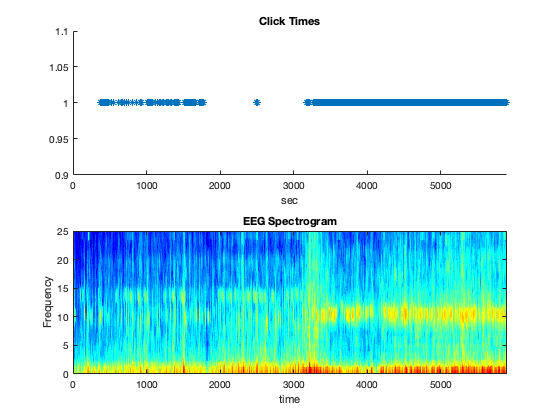

%% Click times, plotting
figure()
ax1 = subplot(2,1,1);
plotclicktimes(subjectID,run)


%% EEG spectrogram of run
dt = timeEEG(2)-timeEEG(1);
params=struct;
params.tapers=[10 19]; % [TW K] TK= time-bandwidth = sampling frequency*spectral width, K = 2*TW - 1
params.Fs=1/dt; % Set sampling rate here
params.fpass=[0 25]; % Set frequency range here
movingwin=[10 2]; % [windowlength windowslide]
[spec, t, f] = mtspecgramc_detrend_laura(EEG,movingwin,params);

%% Plotting specgram details

% figure();
ax2 = subplot(2,1,2);
imagesc(timeEEG,f,log10(spec')) %10*log10(S2)'
set(gca,'YDir','normal')
colormap('jet')
xlabel('time')
ylabel('Frequency')
title('EEG Spectrogram')

axisSpec = ax2.XLim;
linkaxes([ax2,ax1],'x');

ax2.XLim=axisSpec;

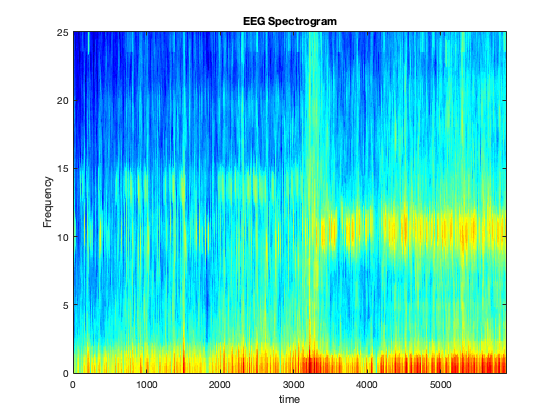

% Plots specgram for sleep staging
figure();
imagesc(timeEEG,f,log10(spec')) %10*log10(S2)'
set(gca,'YDir','normal')
colormap('jet')
xlabel('time')
ylabel('Frequency')
title('EEG Spectrogram')

## Sleep Staging

In this section, please use the slider to go through the intervals of the eeg data and assign a value of sleep, drowsy, or wake. Please click save, to save the assigned sleep stage to the interval.

% Zoom in
remain = rem(max(timeEEG),90);
int_t = 0:90:max(timeEEG);
int_t(length(int_t)+1)=remain+max(int_t);
Time = zeros(length(int_t)-1,2);
for i = 1:length(int_t)-1
    Time(i,1) = int_t(i);
    Time(i,2) = int_t(i+1);
end

Stage = cell(length(Time),1);
interval = cell(length(Time),1);
for i=1:length(Time)
    interval{i} = int2str(i);
end



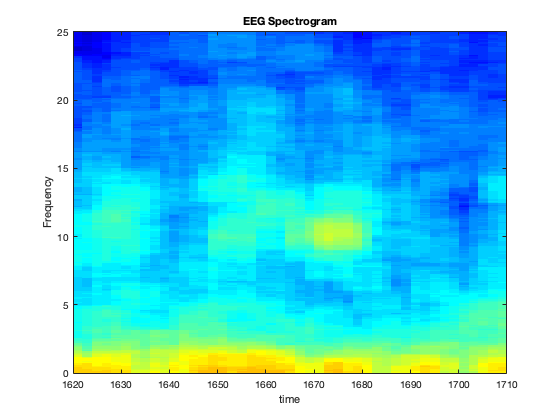




time_interval = 19;




xlim([Time(time_interval,1) Time(time_interval,2)]);

% Plots the stages along the x axis
%bar graph style

% Save sleep staging
Stage{time_interval} = 'Wake';
sleep_info = table(Time,Stage,'RowNames',interval);
disp(sleep_info)

               Time         Stage 
          ______________    ______

    1        0        90    []    
    2       90       180    []    
    3      180       270    []    
    4      270       360    []    
    5      360       450    'Wake'
    6      450       540    'Wake'
    7      540       630    []    
    8      630       720    []    
    9      720       810    []    
    10     810       900    []    
    11     900       990    []    
    12     990      1080    []    
    13    1080      1170    []    
    14    1170      1260    []    
    15    1260      1350    []    
    16    1350      1440    []    
    17    14

% Code that labels a section
dim = [.15 .98 0 0];
str = 'sleep';
annotation("textbox",dim,'String',str);


%delete(findall(gcf,'type','annotation'));

test = 'osceeg17b';